# VARX Model 

## Setup

### Set paths

The VARX package is already included in this folder and will be added here:

addpath('../src/varx/matlab')

The up-to-date package is on github: [https://github.com/lcparra/varx](https://github.com/lcparra/varx) 

## Simple demo of VARX function 

This first example shows the basic usage of the varx() function on union participation and strike data in the US. 

### Background

Causal models are often employed in sociology. This example is motivated by work that has challenged the assumption that union membership provides resources for collective actions causing an increase the number of workers on strike. Alternatively, strikes could motivate more workers to join unions leading to an incrase in membership and thus provide benefits to unions even if demands to employers are not met (Hodder et al., 2016). Unemployment rate is included as an external variable. It is assumed that unemployment rate is not affected by union membership or number of workers on strike, but can influence either of these two variables. 

### Example

We will apply the VARX model on historical data of union membership, number of workers on strike and unemployment rate in the US. A more comprehensive discussion of this example is provided in Parra et al., 2025. 

First load and plot the data:

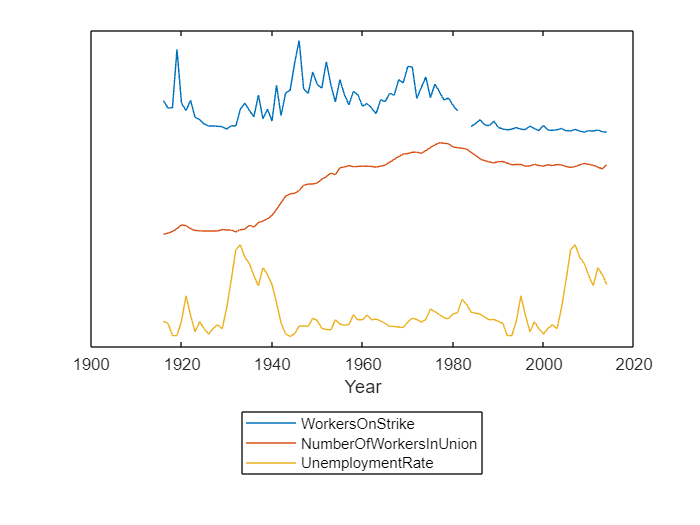

% Load the sample data
load('../data/union_data.mat', 'Y', 'X', 'Y_names', 'X_name', 'year')

% Plot the data over time 
plot(year, [Y, X])
stackplot
legend([Y_names, X_name],'Location','southoutside')
xlabel('Year')

Now we can compute the VARX model. We consider 'WorkersOnStrike' and 'NumberOfWorkersInUnion' as 'output' of the system y(t). They are also refered to as endogenous variables as they influcence each other. Later, in the context of neural data we will call these intrinsic variables. 'UnemploymentRate' is the 'input' to the system x(t). By definition the input is not affected by the output and by other input variables. For analysis of neural data we will also refer to inputs as extrinstic variables. 

% First set the parameters 
na = 3;         % Number of years for the potential effect of instrinsic effects on each other
nb = 3;         % Number of years to consider for external effects
lambda = 0;     % The regularization parameter lambda can control for overfitting

% Compute the VARX model
model = varx(Y,na,X,nb,lambda);

Let's examine the model! 

The VARX model estimates the effect B of the input variable 'UnemploymentRate' on each of the two endogenous variables. The filter B is of size nb x dy, where dy is the number of endogenous variables ('WorkersOnStrike' and 'NumberOfWorkersInUnion'). 

fprintf('Size of B: %d x %d\n', size(model.B))

Size of B: 3 x 2


The internal state of the system is modelled by the filter matrix A, which captures the effects of each intrinsic variable on each of the others. A is of size na x dy x dy. 

fprintf('Size of A: %d x %d x %d\n', size(model.A))

Size of A: 3 x 2 x 2


The computation of A and B filters comprises the system identification. The Granger formalism establishes whether the effect of any channel (extrinsic or intrinsic) on another is significant. This is achieved by comparing the full model to a model with one predictor removed (reduced model). The deviance and effect size R capture the magnitude of this effect, the p-value estimates the statistical significance.  

The model estimates the effect size R for the input variable on each endogenous variable:

fprintf('Size of B R-values: %d x %d\n', size(model.B_Rvalue))

Size of B R-values: 2 x 1


And between each endogenous variable:

fprintf('Size of A R-values: %d x %d\n', size(model.A_Rvalue))

Size of A R-values: 2 x 2


Looking at the effect of unemployment rate we see that it has a significant effect on the number of workers in unions, but not the number of workers on strike:

for i = 1:size(model.B_Rvalue,1)
    fprintf('%s -> %s: R = %1.3f, p = %1.3f\n', X_name{1}, Y_names{i}, model.B_Rvalue(i,1), model.B_pval(i,1))
end

UnemploymentRate -> WorkersOnStrike: R = 0.098, p = 0.829
UnemploymentRate -> NumberOfWorkersInUnion: R = 0.301, p = 0.035


Next, the model shows us the effects of the number of workers on strike and number of workers in unions on each other. The columns in the A matrix are the independent variables, i.e. the cause y(t-1); rows are the dependent variables, i.e. the effect on y(t). Diagonals are the autoregressive effects of variables on themselves. In the example, we see that the effect size of 'WorkersOnStrike' on 'NumberOfWorkersInUnion' (first column on second row), is larger than the effect of 'NumberOfWorkersInUnion' on 'WorkersOnStrike' (second column on first row). This is determined by the order of the variables in the array Y. 

for i = 1:size(model.A_Rvalue,2)
    for j = 1:size(model.A_Rvalue,1)
        if i~=j
            fprintf('%s -> %s: R = %1.3f, p = %1.3f\n', ...
                Y_names{i}, Y_names{j}, model.A_Rvalue(j,i), model.A_pval(j,i))
        end
    end
end

WorkersOnStrike -> NumberOfWorkersInUnion: R = 0.345, p = 0.009
NumberOfWorkersInUnion -> WorkersOnStrike: R = 0.294, p = 0.042


This model therefore supports the claim by Hodder et al., that strikes increase union membership. 

## Analysis of neural data

With some intuition of the VARX model we can delve into neural data. We will demonstrate the effects of the VARX model in comparison to mTRF on the data of one of the patients in Nentwich et al., 2025. The patient watched audiovisual movies during continuous recordings of intracranial EEG and eyetracking. 

### Setup

Download the data from OSF and define the path to the data directory:

data_dir = 'C:\Users\maxne\Documents\varx_data';

## References

Hodder, Andy, et al. "Does strike action stimulate trade union membership growth?." *British Journal of Industrial Relations* 55.1 (2017): 165-186.

Parra, Lucas C., et al. "VARX Granger analysis: Models for neuroscience, physiology, sociology and econometrics." *PloS one* 20.1 (2025): e0313875.

Nentwich, Maximilian, et al. "Intrinsic dynamic shapes responses to external stimulation in the human brain." *eLife* 14 (2025): RP104996.